# **KUKA  Iiwa 7 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Clear the environment.

clc;
clear;
close all;

Load the KUKA Iiwa 7 rigid body tree (RBT) model.

robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "iiwa_link_ee_kuka"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.7 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

close all;
%% Construct voxel obstacle representation for STOMP planner
% Define the workspace (the voxel world limits). Depending on the robot's reach range.
Env_size = [-1, -1, -1; 2, 2, 2];  % [xmin, ymin, zmin] for 1st row, xyz-lengths for 2nd row
voxel_size = [0.02, 0.02, 0.02];  % unit: m
% Binary map: all free space initially, 
binary_world = zeros(Env_size(2, 1) / voxel_size(1), Env_size(2, 2) / voxel_size(2), Env_size(2, 3) / voxel_size(3));
% binary_world_offset = Env_size(1, :)./ voxel_size;

%% XYZ metric representation (in meter) for each voxel 
% !!!!Watch out for the useage of meshgrid:
% [X,Y,Z] = meshgrid(x,y,z) returns 3-D grid coordinates defined by the 
% vectors x, y, and z. The grid represented by X, Y, and Z has size 
% length(y)-by-length(x)-by-length(z).
% The 3D coordinate is of the center of the voxels
[Xw, Yw, Zw] = meshgrid(Env_size(1, 1) + 0.5 * voxel_size(1) : voxel_size(1) : Env_size(1, 1) + Env_size(2, 1) - 0.5 * voxel_size(1), ...
       Env_size(1, 2) + 0.5 * voxel_size(2) : voxel_size(2) : Env_size(1, 2) + Env_size(2, 2) - 0.5 * voxel_size(2), ...
    Env_size(1, 3) + 0.5 * voxel_size(3) : voxel_size(3) : Env_size(1, 3) + Env_size(2, 3) - 0.5 * voxel_size(3));

world = {};
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.15 0.3 0.6]);
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.15 0.3 0.8]);
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.4 0.5 0.6]);

volumeViewer(binary_world);

%% construct signed Euclidean Distance for the voxel world
% Only approximation if the voxel is not a cube
voxel_world_sEDT = prod(voxel_size) ^ (1/3) * sEDT_3d(binary_world);


voxel_world.voxel_size = voxel_size;
voxel_world.voxel = binary_world;
% voxel_world.offset =  binary_world_offset;
voxel_world.world_size = size(binary_world);
voxel_world.Env_size = Env_size; % in metric 
voxel_world.sEDT =  voxel_world_sEDT;


Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

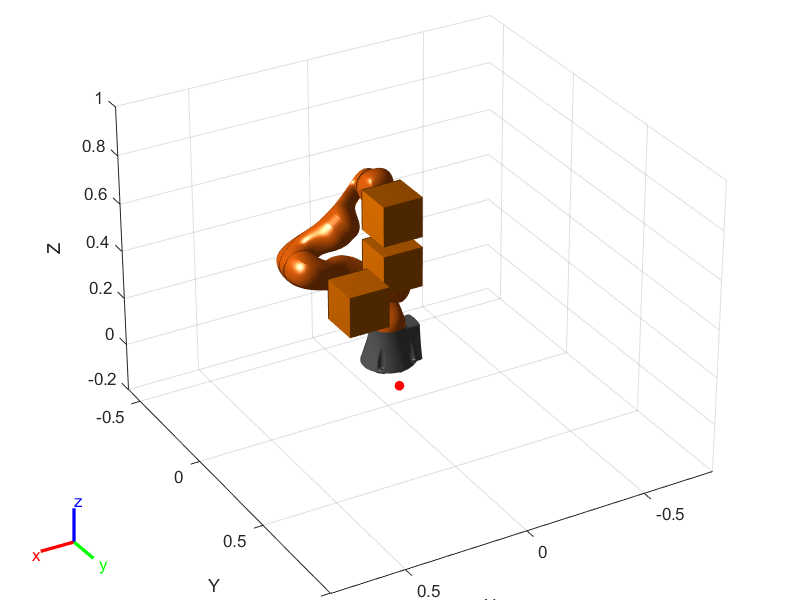

x0 = [currentRobotJConfig', zeros(1,numJoints)];

% Visualize the obstacles and robot manipulator

% Initial visualizer
positions = x0(1:numJoints)';

% figure(): The 1st and 2nd number is the pixel position of the figure relative to
% the monitor display. The 3rd and 4th number are the width and height of
% the figure.
hgif = figure('Position', [375 446 641 480]);
% 'PreservePlot'= True: The function does not overwrite previous plots displayed by calling show. 
% This setting functions similarly to hold on for a standard MATLAB® figure, 
% but is limited to robot body frames. When you specify this argument as 
% false, the function overwrites previous plots of the robot.
% 'Frames': Display body frames
ax1 = show(robot, positions(:,1),'PreservePlot', false, 'Frames', 'off');
% view(az,el) sets the azimuth and elevation angles of the camera's line of
% sight for the current axes
view(150,29)
hold on
% set the x,y,z, data limits of the figure
axis([-0.8 0.8 -0.6 1.0 -0.2 1.0]);
% plot the final position
plot3(poseFinal(1), poseFinal(2), poseFinal(3),'r.','MarkerSize',20)

% Visualize collision world specified in previous scripts
for i=1:numel(world)
    [~,pObj] = show(world{i});
    pObj.LineStyle = 'none';
end

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Elapsed time is 13.612519 seconds.


Qtheta = 1.0232e+04

RAR = 17.3083

Elapsed time is 13.091636 seconds.


Qtheta = 8.6743e+03

RAR = 17.3216

Elapsed time is 13.648488 seconds.


Qtheta = 7.0541e+03

RAR = 17.3269

Elapsed time is 12.163889 seconds.


Qtheta = 6.0025e+03

RAR = 17.3281

Elapsed time is 12.911537 seconds.


Qtheta = 4.8201e+03

RAR = 17.3367

Elapsed time is 13.333858 seconds.


Qtheta = 4.1029e+03

RAR = 17.3407

Elapsed time is 13.698425 seconds.


Qtheta = 3.3315e+03

RAR = 17.3517

Elapsed time is 13.040552 seconds.


Qtheta = 2.6505e+03

RAR = 17.3556

Elapsed time is 12.482596 seconds.


Qtheta = 1.8600e+03

RAR = 17.3652

Elapsed time is 12.146722 seconds.


Qtheta = 1.6280e+03

RAR = 17.3691

Elapsed time is 13.246192 seconds.


Qtheta = 1.3439e+03

RAR = 17.3709

Elapsed time is 13.305857 seconds.


Qtheta = 1.2542e+03

RAR = 17.3710

Elapsed time is 13.976143 seconds.


Qtheta = 1.1364e+03

RAR = 17.3759

Elapsed time is 13.225286 seconds.


Qtheta = 1.0971e+03

RAR = 17.3777

Elapsed time is 13.424568 seconds.


Qtheta = 1.0874e+03

RAR = 17.3815

Elapsed time is 12.302033 seconds.


Qtheta = 1.0383e+03

RAR = 17.3878

Elapsed time is 12.842301 seconds.


Qtheta = 992.9083

RAR = 17.3894

Elapsed time is 13.152526 seconds.


Qtheta = 961.0805

RAR = 17.3922

Elapsed time is 11.688426 seconds.


Qtheta = 963.1893

RAR = 17.3902

Elapsed time is 12.514087 seconds.


Qtheta = 932.0183

RAR = 17.3862

Elapsed time is 13.289151 seconds.


Qtheta = 947.9134

RAR = 17.3913

Elapsed time is 15.136316 seconds.


Qtheta = 935.5974

RAR = 17.3838

Elapsed time is 12.391249 seconds.


Qtheta = 899.3442

RAR = 17.3778

Elapsed time is 14.239871 seconds.


Qtheta = 886.2224

RAR = 17.3799

Elapsed time is 14.269640 seconds.


Qtheta = 848.0055

RAR = 17.3830

Elapsed time is 13.952413 seconds.


Qtheta = 831.1311

RAR = 17.3801

Elapsed time is 15.256409 seconds.


Qtheta = 871.4098

RAR = 17.3863

Elapsed time is 15.521127 seconds.


Qtheta = 856.2403

RAR = 17.3859

Elapsed time is 14.187514 seconds.


Qtheta = 820.6976

RAR = 17.3895

Elapsed time is 14.020256 seconds.


Qtheta = 793.3108

RAR = 17.3914

Elapsed time is 13.472043 seconds.


Qtheta = 784.1363

RAR = 17.3946

Elapsed time is 13.421073 seconds.


Qtheta = 736.7927

RAR = 17.3921

Elapsed time is 14.289928 seconds.


Qtheta = 708.9683

RAR = 17.3832

Elapsed time is 14.391009 seconds.


Qtheta = 701.4601

RAR = 17.3853

Elapsed time is 13.677049 seconds.


Qtheta = 671.9548

RAR = 17.3833

Elapsed time is 14.692253 seconds.


Qtheta = 683.3913

RAR = 17.3843

Elapsed time is 12.882313 seconds.


Qtheta = 677.3611

RAR = 17.3787

Elapsed time is 12.274804 seconds.


Qtheta = 672.7856

RAR = 17.3796

Elapsed time is 12.966527 seconds.


Qtheta = 650.8339

RAR = 17.3753

Elapsed time is 14.234093 seconds.


Qtheta = 632.6593

RAR = 17.3758

Elapsed time is 14.420428 seconds.


Qtheta = 608.1254

RAR = 17.3698

Elapsed time is 14.468014 seconds.


Qtheta = 613.2882

RAR = 17.3737

Elapsed time is 15.076611 seconds.


Qtheta = 606.2860

RAR = 17.3718

Elapsed time is 15.342162 seconds.


Qtheta = 592.3507

RAR = 17.3674

Elapsed time is 13.702716 seconds.


Qtheta = 589.8891

RAR = 17.3663

Elapsed time is 13.687987 seconds.


Qtheta = 593.4764

RAR = 17.3612

Elapsed time is 13.686623 seconds.


Qtheta = 587.1908

RAR = 17.3666

Elapsed time is 14.499128 seconds.


Qtheta = 576.7707

RAR = 17.3650

Elapsed time is 14.739004 seconds.


Qtheta = 571.5003

RAR = 17.3632

Elapsed time is 14.621025 seconds.


Qtheta = 549.5320

RAR = 17.3677

Elapsed time is 14.603613 seconds.


Qtheta = 550.5678

RAR = 17.3694

Elapsed time is 14.007566 seconds.


Qtheta = 555.1142

RAR = 17.3684

Elapsed time is 14.461060 seconds.


Qtheta = 543.7638

RAR = 17.3730

Elapsed time is 14.196481 seconds.


Qtheta = 546.7185

RAR = 17.3697

Elapsed time is 13.367398 seconds.


Qtheta = 540.6293

RAR = 17.3741

Elapsed time is 14.528229 seconds.


Qtheta = 533.4697

RAR = 17.3770

Elapsed time is 13.260449 seconds.


Qtheta = 523.9777

RAR = 17.3815

Elapsed time is 13.632217 seconds.


Qtheta = 517.7874

RAR = 17.3800

Elapsed time is 13.420785 seconds.


Qtheta = 514.9600

RAR = 17.3797

Elapsed time is 13.494506 seconds.


Qtheta = 520.8001

RAR = 17.3780

Elapsed time is 14.330192 seconds.


Qtheta = 511.7717

RAR = 17.3824

Elapsed time is 15.568995 seconds.


Qtheta = 507.4668

RAR = 17.3833

Elapsed time is 17.663650 seconds.


Qtheta = 529.0772

RAR = 17.3808

Elapsed time is 14.729349 seconds.


Qtheta = 519.1405

RAR = 17.3823

Elapsed time is 14.688998 seconds.


Qtheta = 514.4274

RAR = 17.3759

Elapsed time is 14.839287 seconds.


Qtheta = 508.5207

RAR = 17.3764

Elapsed time is 13.757437 seconds.


Qtheta = 521.2668

RAR = 17.3729

Elapsed time is 14.508356 seconds.


Qtheta = 516.0534

RAR = 17.3748

Elapsed time is 13.949341 seconds.


Qtheta = 508.4535

RAR = 17.3721

Elapsed time is 14.513791 seconds.


Qtheta = 491.3898

RAR = 17.3723

Elapsed time is 14.366013 seconds.


Qtheta = 468.6998

RAR = 17.3708

Elapsed time is 14.773943 seconds.


Qtheta = 461.2304

RAR = 17.3681

Elapsed time is 15.232336 seconds.


Qtheta = 464.0320

RAR = 17.3689

Elapsed time is 17.431504 seconds.


Qtheta = 463.5041

RAR = 17.3741

Elapsed time is 14.930644 seconds.


Qtheta = 445.0688

RAR = 17.3708

Elapsed time is 15.799971 seconds.


Qtheta = 443.7007

RAR = 17.3741

Elapsed time is 16.218338 seconds.


Qtheta = 450.4680

RAR = 17.3664

Elapsed time is 15.449488 seconds.


Qtheta = 461.5405

RAR = 17.3626

Elapsed time is 14.817081 seconds.


Qtheta = 432.0447

RAR = 17.3661

Elapsed time is 15.090284 seconds.


Qtheta = 469.3122

RAR = 17.3650

Elapsed time is 16.054134 seconds.


Qtheta = 455.8668

RAR = 17.3634

Elapsed time is 15.468768 seconds.


Qtheta = 427.3291

RAR = 17.3588

Elapsed time is 14.914409 seconds.


Qtheta = 406.2037

RAR = 17.3582

Elapsed time is 15.538310 seconds.


Qtheta = 398.9624

RAR = 17.3577

Elapsed time is 13.260987 seconds.


Qtheta = 398.8158

RAR = 17.3608

Elapsed time is 12.682225 seconds.


Qtheta = 388.7573

RAR = 17.3552

Elapsed time is 15.923220 seconds.


Qtheta = 384.6905

RAR = 17.3579

Elapsed time is 12.574338 seconds.


Qtheta = 393.0073

RAR = 17.3569

Elapsed time is 12.215287 seconds.


Qtheta = 382.8161

RAR = 17.3577

Elapsed time is 14.193769 seconds.


Qtheta = 370.4439

RAR = 17.3574

Elapsed time is 11.143549 seconds.


Qtheta = 359.8997

RAR = 17.3616

Elapsed time is 11.544674 seconds.


Qtheta = 356.3091

RAR = 17.3595

Elapsed time is 11.158753 seconds.


Qtheta = 348.4846

RAR = 17.3601

Elapsed time is 11.592674 seconds.


Qtheta = 348.2000

RAR = 17.3557

Elapsed time is 11.702623 seconds.


Qtheta = 350.3449

RAR = 17.3560

Elapsed time is 12.102861 seconds.


Qtheta = 334.5285

RAR = 17.3592

Elapsed time is 12.258519 seconds.


Qtheta = 338.3917

RAR = 17.3617

Elapsed time is 12.849788 seconds.


Qtheta = 341.4456

RAR = 17.3668

Elapsed time is 12.532247 seconds.


Qtheta = 320.1797

RAR = 17.3665

Elapsed time is 12.256458 seconds.


Qtheta = 299.3795

RAR = 17.3665

Elapsed time is 11.566252 seconds.


Qtheta = 298.9845

RAR = 17.3647

Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   1


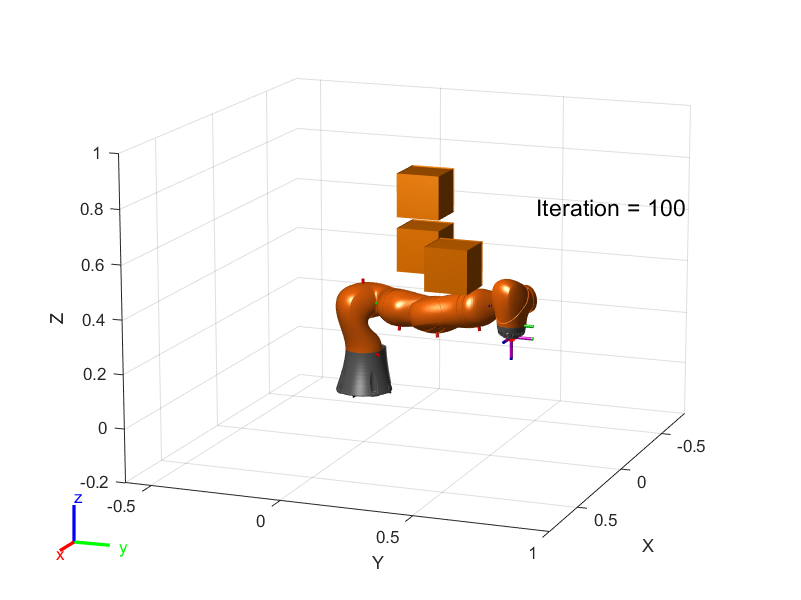

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.